clc; clear all; close all;

## Step 1: Latin Hypercube Sampling

Utilize the LHS (Latin Hypercube Sampling) to generate the normal distribution $G_1(u = 0, \sigma = 1)$. At this moment, the elements in $G_1$ is independent with each other.


X =[0:10:50]';% X coordinate X mesh node
Y =[0:10:50]';% Y coordinate Y mesh node
Node_Coordi = [];
%%loop to get the mid-point of each element
for i = 1:size(X,1)
    for j= 1:size(Y,1)
        Node{i,j} = [X(i,1),Y(j,1)]; 
        
        if (i < size(X,1) ) & (j < size(Y,1))
            Midpoint_Node{i,j} = [mean(X(i:i+1,1)),mean(Y(j:j+1,1))];
            Node_Coordi = [Node_Coordi; Midpoint_Node{i,j}(1),Midpoint_Node{i,j}(2)];
        end        
    end    
end


Node_Num = length(Node_Coordi);%obtian the number of the element (or the mid-point)
G1=lhsnorm(0,1, Node_Num);%LhS function to generate normal distribution


## Step 2: Obtain the autocorrelated covariance matrix ***C***

Obtain the autocorrelated covariance matrix ***C***. Cholesky decomposition is used to get the lower triangular matrix ***L ***of ***C.***

C = [];% create empty C matrix
dv = 1;% vertical SoF = 1m
dh = 1;% horizontal SoF = 1m
%loop to calcuate the autocorrelated covariance matrix C with SNX function
for i = 1:Node_Num
    for j = 1:Node_Num
        dx = abs(Node_Coordi(i,1) - Node_Coordi(j,1));
        dy = abs(Node_Coordi(i,2) - Node_Coordi(j,2));        
        C(i,j) = exp(-2*(dx/dh+dy/dv));
    end
end

L = chol(C)';% cholesky decompositoin to generate the lower matrix L

## Step 3: Get the Gaussian field ***G******2*** = ***LG1***

Get the Gaussian field ***G******2*** = ***LG******1. ***After multiplying with matrix ***L, G******2 ***is still the Gaussian random field, but linked to the spatial correlation length SoF

G2 =L*G1;

## Step 4: Change the Gaussian  considering the SoF ***G******2***  into non-Gaussian (Log-normal) ***G******3***


$$G3 =\exp(\mu_{lns_{u} } +\sigma_{ln_{su}}G2) $$



$$\sigma_{ln_{su}} = \sqrt{ln(1+COV_{s_{u}}^{2} )} $$
 


$$\mu_{lns_{u} } = ln\mu_{s_{u}} - \frac{1}{2} \sigma_{ln_{s_{u}}}^{2} $$


SLN is the sigma; MLN is the $\mu_{lnsu }$

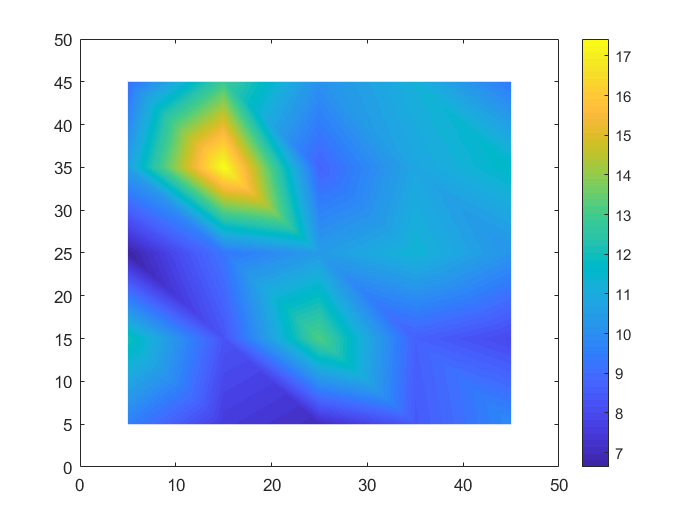

mu = [10];%mean value = 10
sigma = [2];%variance sigma = 2
COV = sigma./mu;
SLN=(log(1+COV.^2))^0.5;%calculate the SLN
MLN=log(mu)-SLN^2./2; %calculate the MLN
G3 = exp(MLN+SLN.*G2);%calculate the G3
Length_G3 = length(G3);%obtain the length of G3
X_Matrix = reshape(Node_Coordi(:,1),sqrt(Length_G3),sqrt(Length_G3));
Y_Matrix = reshape(Node_Coordi(:,2),sqrt(Length_G3),sqrt(Length_G3));
G3 = reshape(G3,sqrt(Length_G3),sqrt(Length_G3));
s = surf(X_Matrix,Y_Matrix,G3);
view(2);
s.EdgeColor = 'none';
colormap parula;
grid off;
box on;
colorbar;
shading interp;

xlim([0.0 50.0])
ylim([0.0  50.0])
set(gca,'xtick',0:10:50);

%set(gca,'xtick',[],'ytick',[]);
% Length_G3 = length(G3);%obtain the length of G3
% M = reshape(G3,sqrt(Length_G3),sqrt(Length_G3));%reshape G3 to get heatmap
% hm = heatmap(M);
% hm.CellLabelColor = 'none';
% grid off;
% colormap(hm,'jet');
%heatmap(string(Node_Coordi(:,1)),string(Node_Coordi(:,2)),G3);